**Interactive Cell counter Analysis Program**

Copyright © 2023 Elizabeth Bowen, UCLA

Notes: Selecting parameters will automatically run each section, but the Run button @ bottom of each section can be used to run a section without changing the parameters.

**1. Blur Image & Convert to Grayscale**

Put in the file path to the folder with the image you want to use, and enter the file name into the imgTitle field, then click enter:

% Make sure that you're in the folder with the images you want to use
%loadImage("C3 0h.tif");
addpath("/Users/elizabeth 1/Desktop/Wu Lab/Kaileys Images/Cell Assay Analysis Package"); %load in functions for this package
filePath = "/Users/elizabeth 1/Desktop/Wu Lab/Kaileys Images/10C";
cd (filePath);
fileList = dir(fullfile(filePath, '*.tif'));  % List all PNG files (modify the extension as needed)

% Extract the filenames from the structure
filenames = {fileList.name}'

filenames = 35×1 cell array
    {'40ug crex 1 10x a.tif'        }
    {'40ug crex 1 10x b.tif'        }
    {'40ug crex 1 10x c.tif'        }
    {'40ug crex 1 10x d.tif'        }
    {'40ug crex 1 10x e.tif'        }
    {'40ug crex 1 10x f.tif'        }
    {'40ug crex 2 10x a.tif'        }
    {'40ug crex 2 10x b.tif'        }
    {'40ug crex 2 10x d.tif'        }
    {'40ug crex 2 10x e.tif'        }
    {'40ug crex 2 10x f.tif'        }
    {'40ug crex 3 10x a.tif'        }
    {'40ug crex 3 10x b.tif'        }
    {'40ug crex 3 10x c.tif'        }
    {'40ug crex 3 10x d.tif'        }
    {'40ug crex 3 10x e.tif'        }
    {'40ug crex 3 10x f.tif'        }
    {'40ug crex 4 10x a.tif'        }
    {'40ug crex 4 10x b.tif'        }
    {'40ug crex 4 10x c.tif'        }
    {'40ug crex 4 10x d.tif'        }
    {'40ug crex 4 10x e.tif'        }
    {'40ug crex 4 10x f.tif'        }
    {'In PDF) -E2c.tif'             }
    {'In PDF) 40ug crex 2 10x c.tif'}
    {'control 1 10x a.

photoNumber = length(filenames);
%allow user to use slider to iterate through images in the specified folder
%(don't have to type in image neame each time)
i =21;
imgTitle = string(filenames(i))

imgTitle = "40ug crex 4 10x d.tif"

img1 = imread(imgTitle); %read in image
img = rgb2gray(img1); %convert to grayscale
img_blurred = imgaussfilt(img);
% imagesc(img_blurred)


% Define the window sizes for variance calculation
windowSizes = [3, 5, 7, 9];
        
% Initialize a mask to store the blurry regions
blurryMask = false(size(img_blurred));

% Calculate variance at different window sizes
for i = 1:numel(windowSizes)
            windowSize = windowSizes(i);
            
            % Calculate the local variance using imfilter and imgaussfilt
                localVariance = imfilter(double(img_blurred).^2, ones(windowSize)/windowSize^2, 'replicate') - imgaussfilt(double(img_blurred), windowSize).^2;
            
            % Find the blurry regions based on variance values
            blurryRegions = localVariance <= 90;
            
            % Accumulate the blurry regions
            blurryMask = blurryMask | blurryRegions;
end
        
% Apply the blurry mask to the original image
blurryImage = img_blurred;
%aboveThresholdMask = img_blurred > graythresh(img_blurred);
%blurryImage(blurryMask & aboveThresholdMask) = 0;  % Set to white

blurryImage(~blurryMask) = 0; %create an image that displays original
% grayscale values of blurry regions, and non-blurry regions set to 0 (black)

    
     

 
    figure
%    imagesc(img1)
    figure
%     imagesc(blurryImage), colormap gray
    blurryBinary = ~blurryImage; %Binary image where white = blurry regions
    
    brightnessThreshold = 70 % Example threshold value

brightnessThreshold = 70

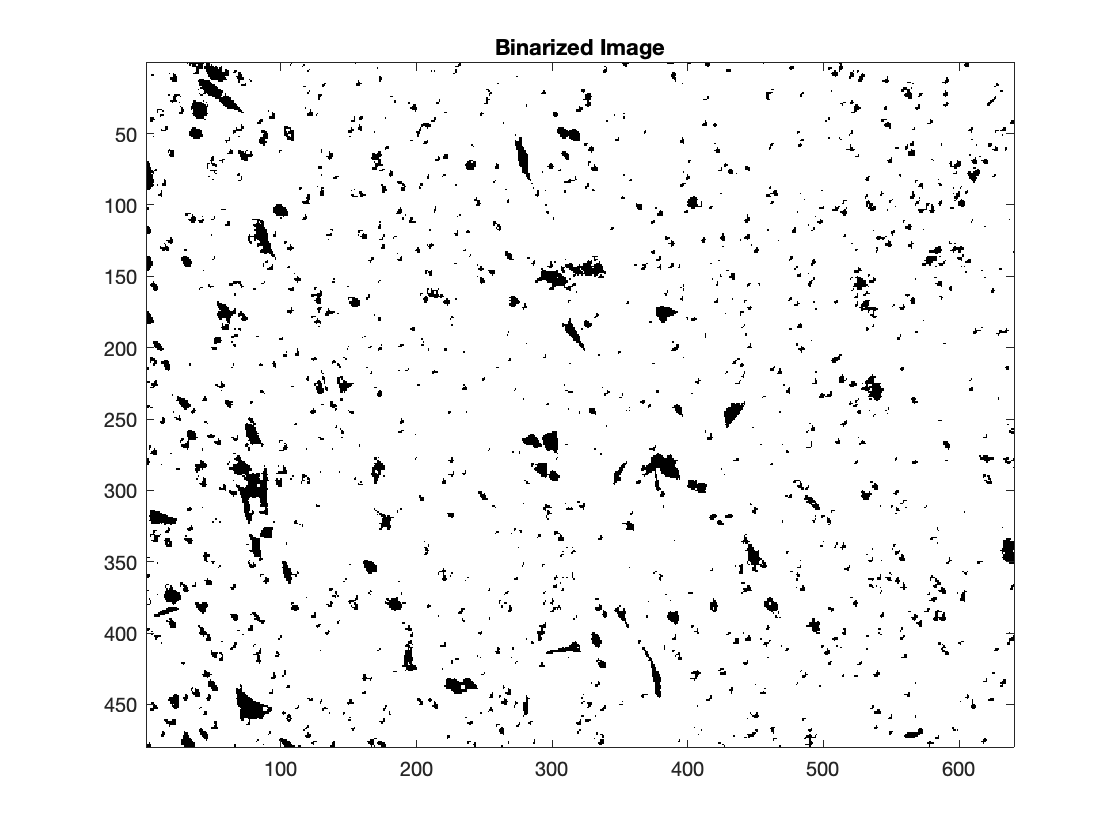

    
    % Create a binary mask for regions above the brightness threshold
    aboveThresholdMask = img_blurred > brightnessThreshold;
    
    % Set the corresponding regions in 'back' to white
    blurryBinary(aboveThresholdMask) = 1;
%     figure, imagesc(blurryBinary), colormap gray
    

    % Apply a threshold to separate foreground and background
    [thresholded, sensitivity] = adaptiveThreshold(img_blurred); 
    
%    figure, imagesc(thresholded), colormap gray
%     
%     % Remove blurry regions under a certain intensity threshold
%     graythresh(img_blurred) %for reference
%     thresholded_blurryImage = blurryImage >graythresh(img_blurred);
%     figure, imagesc(thresholded_blurryImage), colormap gray
    thresholded(blurryBinary) = 1;
    bw = thresholded;

    
    %display original image
   
    
    figure
    colormap gray
    imagesc(bw),  title('Binarized Image')  

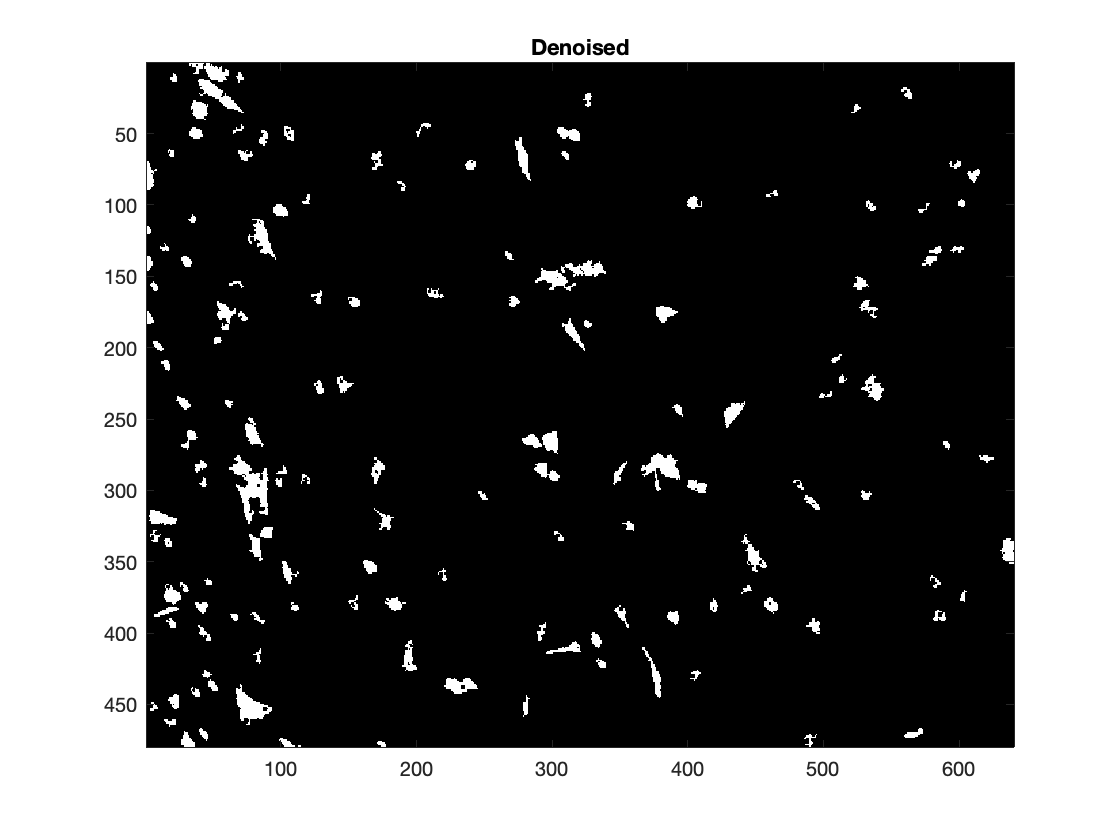


    bw2 = imcomplement(bw);
% imagesc(bw2)
% stats = regionprops(imcomplement(bw), 'Area');
% 
% % Access the area values
% areas = [stats.Area]'
% histogram(areas, 'NumBins', 300), xlim([0,40])
denoised = bwareaopen(bw2, 20);
imagesc(denoised), title('Denoised')

%imagesc(denoised), title('Specks Removed')
labeledImage = bwlabel(denoised);
% Calculate the properties of the foreground objects
props = regionprops(labeledImage, denoised, 'Area');

% Extract the area values of foreground objects
foregroundAreas = [props.Area];

%count cells using distinct foreground objects & breaking up area of large
%clustered objects
cells = numel(foregroundAreas) %# of foreground objects

cells = 149

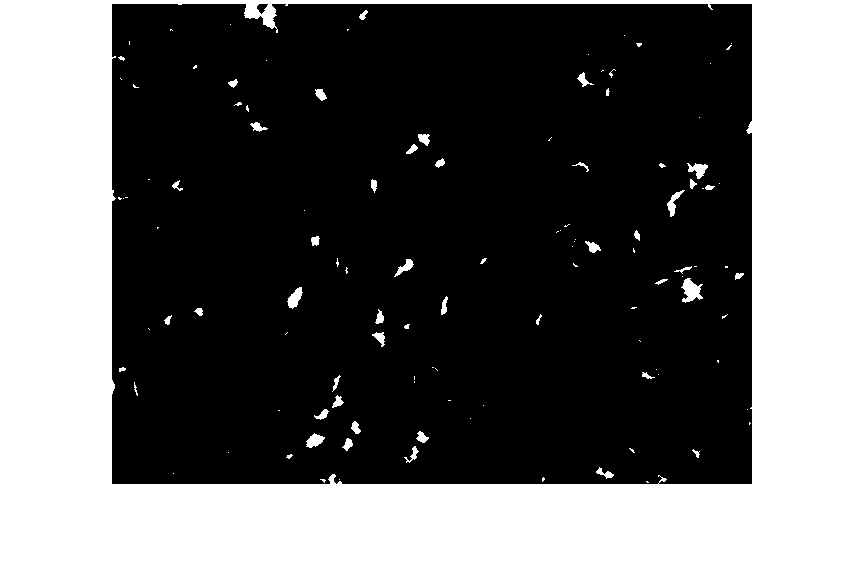


se = strel('disk', 2);
eroded = imerode(denoised, se);
dilated = imdilate(eroded, se);
imshow(eroded)

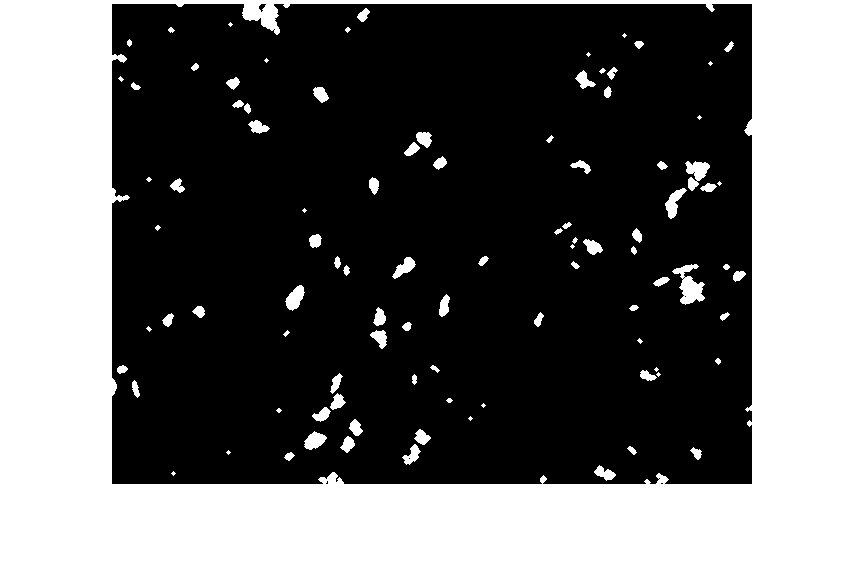

imshow(dilated)

labeledImage2 = bwlabel(eroded);
props2 = regionprops(labeledImage2, eroded, 'Area');
foregroundAreas2 = [props2.Area];
cells2 = numel(foregroundAreas2)

cells2 = 127


sum(foregroundAreas);

clusteredCells = foregroundAreas(foregroundAreas > 100); %extract large objects that represent multiple cells clustered tog
num = numel(clusteredCells); %get # of elements
cells = cells-num; %remove those from the cell count 
clusteredArea = sum(clusteredCells); %get total area of clustered cells
%73 = avg cell size
cells = round(cells + clusteredArea/73) %add clustered area ÷ avg cell size & round to make whole #

cells = 244



%where store data from image analysis (table & montage)
tableName = "10C_Migration_Data"+'.xls'; %excel file where you want to store analysis stats
filePath = "/Users/elizabeth 1/Desktop/Wu Lab/Kaileys Images/10C";  %directory in which to create/look for table & to store images
cd(filePath)



C = imfuse(denoised,img1,'montage'); %show eroded in montage if using eroion for segmentation

S = extractBefore(imgTitle, '.');
fileName = "MONTAGE " + S + '.jpg';
imwrite(C,fileName)



fprintf('Image Montage (Downloaded): [%s]', fileName)

Image Montage (Downloaded): [MONTAGE control 1 10x d.jpg]

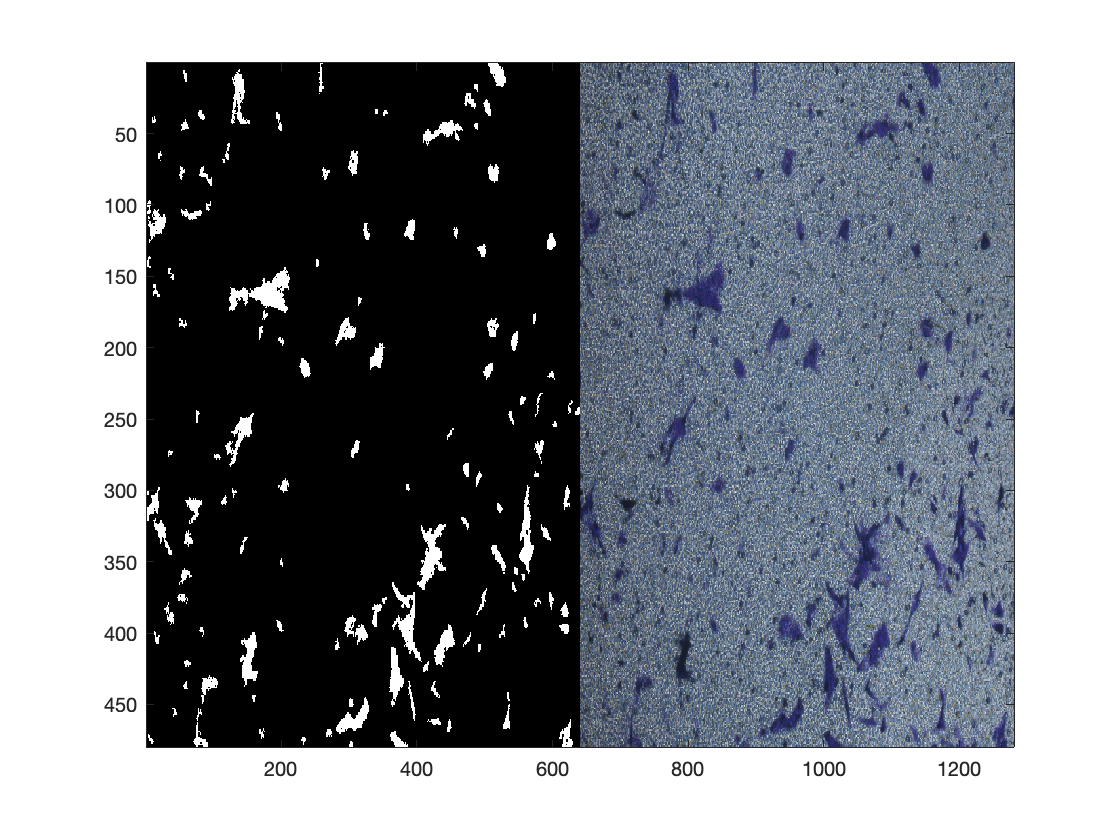

imagesc(C)


%create an excel file with tableName if such a file does not already exist;
if ~isfile(tableName) %if the table does not already exist
    colNames = {'Photo Name', 'cell count'};
    data = cell(1,2); % create a cell array with one row and the same number of columns as colNames
    table = [cell2table(colNames, 'VariableNames', colNames); cell2table(data, 'VariableNames', colNames)]
    writetable(table, tableName);
    existingTable = readtable(tableName);
    existingTable(1,:) = []; %remove duplicate column names row
else
    existingTable = readtable(tableName); %no need to remove duplicate col name row in this case
end

table = 2×2 table
      Photo Name        cell count  
    ______________    ______________

    {'Photo Name'}    {'cell count'}
    {0×0 double  }    {0×0 double  }




fprintf('This table is stored as %s in %s:', tableName, filePath)

This table is stored as 10_Migration_Data.xls in /Users/elizabeth 1/Desktop/Wu Lab/Kaileys Images/10C:



newRow = {imgTitle, cells}; 


data = [existingTable;newRow]; %add data from analysis
%T = unique(data,'rows', 'stable'); %make sure there are no duplicate lines
% Find the unique values in PhotoName column
[~, ia, ~] = unique(flipud(data.PhotoName),'rows', 'stable');
ia = size(data,1) - ia + 1;% Select only the rows that contain unique values. If you ran code for
% the same image >1 time, the program will save the most recent version of
analysisStats = flipud(data(ia, :))

analysisStats = 1×2 table
          PhotoName          cellCount
    _____________________    _________

    "control 1 10x d.tif"     {[244]} 



writetable(analysisStats, tableName, 'WriteMode', 'overwrite'); %add data to table

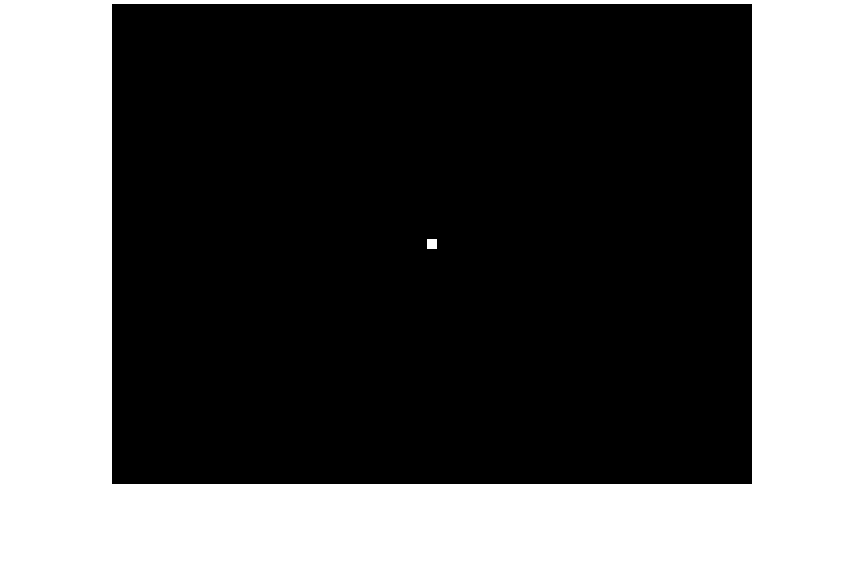

% Set the size of the image
imageSize = [480, 640];  % Adjust the dimensions as needed

% Create the binary image matrix
binaryImage = zeros(imageSize);

% Define the desired area of the object
objectArea = 100;  % Adjust the area as needed

% Calculate the dimensions of the object based on the desired area
objectSize = [sqrt(objectArea), sqrt(objectArea)];

% Calculate the starting pixel position for the object
startPos = floor((imageSize - objectSize) / 2) + 1;

% Set the pixels of the object to white
binaryImage(startPos(1):startPos(1)+objectSize(1)-1, startPos(2):startPos(2)+objectSize(2)-1) = 1;

% Set the remaining pixels to the background value (0)
backgroundValue = 0;
binaryImage(binaryImage == 0) = backgroundValue;

% Display the binary image
imshow(binaryImage)


size(denoised)

ans =    480   640
